# **POD applied to an image**

*V. Matray*

clear all
close all
clc

## POD by SVD

load original image

UCimage = imread('callas.jpg');
UCimage = im2double(UCimage(:,:,1));
figure
subplot(1,2,1)
colormap(gray); imagesc(UCimage(:,:));axis equal;axis tight; axis off;
title ('Maria Callas')

get dimensions of the image

n_T = size(UCimage, 1);
n_M = size(UCimage, 2);
U = UCimage;

SVD on the image

[phi,S,V] = svd(U);

Order for reconstruction ?

order = 25;

Initialize the reconstruction 

Ui = zeros(n_M,n_T)';

Reconstruction :

for o = 1:order
    for i = 1:n_T
       Ui(:,i) =  Ui(:,i)+ phi(:,o)*(U(:,i)'*phi(:,o)) ;
    end
Ui = Ui +S(o,o)*phi(:,o)*V(:,o)';
end

Optional challenge: build Ui using a single Matlab line 

%TODO

plot

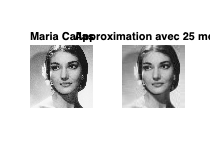

subplot(1,2,2)
colormap(gray); imagesc(Ui(:,:));axis equal;axis tight; axis off;
title("Approximation avec "+order+" modes")

## Calculation of the reconstruction error

Plot the reconstruction error as a function of the number of modes used. The reconstruction error considered here will be calculated with the norm of your choice (you can use the "norm" function of Matlab it's the fastest/ easiest way ;) ). 

%TODO
M = (S*phi*V');
Mord = zeros(size(M));
for o = 1:order
    Mord = Mord + S(o,o)*phi(:,o)*V(:,o)'
end

Mord =     0.6383    0.6385    0.6391    0.6389    0.6386    0.6396    0.6405    0.6395    0.6388    0.6412    0.6417    0.6408    0.6411    0.6413    0.6423    0.6421    0.6418    0.6421    0.6417    0.6419    0.6411    0.6401    0.6410    0.6408    0.6378    0.6380    0.6388    0.6393    0.6386    0.6395    0.6399    0.6398    0.6422    0.6412    0.6394    0.6402    0.6413    0.6417    0.6423    0.6410    0.6401    0.6405    0.6410    0.6409    0.6398    0.6402    0.6392    0.6402    0.6416    0.6421
    0.6433    0.6435    0.6441    0.6439    0.6436    0.6447    0.6455    0.6445    0.6438    0.6462    0.6467    0.6459    0.6461    0.6464    0.6474    0.6471    0.6468    0.6471    0.6467    0.6469    0.6461    0.6451    0.6461    0.6459    0.6428    0.6430    0.6438    0.6443    0.6436    0.6445    0.6449    0.6449    0.6472    0.6462    0.6444    0.6452    0.6463    0.6467    0.6474    0.6461    0.6451    0.6456    0.6460    0.6459    0.6448    0.6452    0.6443    0.6452    0.6466  

Mord =     0.6499    0.6506    0.6513    0.6515    0.6518    0.6528    0.6538    0.6534    0.6532    0.6552    0.6564    0.6548    0.6549    0.6552    0.6564    0.6566    0.6561    0.6563    0.6561    0.6569    0.6557    0.6540    0.6553    0.6557    0.6531    0.6531    0.6535    0.6543    0.6540    0.6547    0.6543    0.6542    0.6562    0.6551    0.6552    0.6556    0.6564    0.6563    0.6570    0.6569    0.6563    0.6565    0.6570    0.6571    0.6561    0.6564    0.6562    0.6566    0.6574    0.6584
    0.6538    0.6545    0.6552    0.6554    0.6556    0.6566    0.6576    0.6572    0.6569    0.6590    0.6601    0.6586    0.6587    0.6590    0.6602    0.6604    0.6598    0.6601    0.6598    0.6606    0.6594    0.6578    0.6591    0.6594    0.6567    0.6568    0.6572    0.6579    0.6577    0.6583    0.6581    0.6579    0.6599    0.6589    0.6588    0.6592    0.6601    0.6601    0.6608    0.6605    0.6599    0.6601    0.6606    0.6607    0.6597    0.6600    0.6597    0.6601    0.6610  

Mord =     0.6557    0.6566    0.6568    0.6569    0.6572    0.6579    0.6588    0.6583    0.6575    0.6599    0.6612    0.6595    0.6589    0.6591    0.6604    0.6606    0.6601    0.6599    0.6590    0.6597    0.6588    0.6568    0.6582    0.6589    0.6558    0.6564    0.6565    0.6570    0.6565    0.6569    0.6564    0.6561    0.6581    0.6565    0.6562    0.6572    0.6579    0.6574    0.6579    0.6578    0.6575    0.6576    0.6577    0.6572    0.6560    0.6564    0.6566    0.6569    0.6578    0.6580
    0.6619    0.6627    0.6627    0.6628    0.6630    0.6636    0.6645    0.6638    0.6628    0.6654    0.6667    0.6650    0.6642    0.6643    0.6657    0.6657    0.6653    0.6650    0.6638    0.6645    0.6636    0.6616    0.6630    0.6638    0.6604    0.6613    0.6613    0.6617    0.6611    0.6614    0.6608    0.6605    0.6626    0.6608    0.6601    0.6615    0.6621    0.6615    0.6620    0.6618    0.6614    0.6616    0.6615    0.6608    0.6595    0.6600    0.6602    0.6606    0.6616  

Mord =     0.6626    0.6635    0.6648    0.6629    0.6634    0.6652    0.6659    0.6641    0.6622    0.6643    0.6657    0.6645    0.6633    0.6622    0.6642    0.6649    0.6638    0.6635    0.6626    0.6626    0.6618    0.6595    0.6613    0.6606    0.6572    0.6579    0.6570    0.6588    0.6565    0.6555    0.6566    0.6568    0.6574    0.6558    0.6552    0.6562    0.6575    0.6557    0.6557    0.6550    0.6556    0.6548    0.6549    0.6544    0.6526    0.6539    0.6528    0.6532    0.6516    0.6536
    0.6693    0.6703    0.6715    0.6694    0.6698    0.6716    0.6722    0.6702    0.6679    0.6702    0.6716    0.6704    0.6690    0.6677    0.6698    0.6705    0.6693    0.6689    0.6677    0.6676    0.6669    0.6645    0.6664    0.6657    0.6620    0.6629    0.6619    0.6637    0.6610    0.6598    0.6611    0.6612    0.6618    0.6600    0.6590    0.6603    0.6617    0.6597    0.6595    0.6587    0.6594    0.6585    0.6584    0.6578    0.6557    0.6572    0.6561    0.6565    0.6549  

Mord =     0.6555    0.6566    0.6578    0.6552    0.6538    0.6552    0.6545    0.6512    0.6515    0.6506    0.6483    0.6479    0.6483    0.6462    0.6459    0.6462    0.6450    0.6424    0.6403    0.6406    0.6387    0.6363    0.6359    0.6344    0.6303    0.6316    0.6314    0.6306    0.6277    0.6249    0.6255    0.6270    0.6283    0.6249    0.6195    0.6234    0.6246    0.6243    0.6243    0.6210    0.6213    0.6216    0.6213    0.6190    0.6168    0.6163    0.6158    0.6162    0.6161    0.6162
    0.6629    0.6639    0.6651    0.6624    0.6610    0.6625    0.6619    0.6584    0.6582    0.6577    0.6557    0.6553    0.6553    0.6531    0.6531    0.6535    0.6523    0.6497    0.6475    0.6476    0.6459    0.6435    0.6433    0.6418    0.6374    0.6389    0.6385    0.6380    0.6348    0.6320    0.6327    0.6341    0.6354    0.6318    0.6265    0.6304    0.6317    0.6310    0.6309    0.6277    0.6281    0.6283    0.6278    0.6255    0.6232    0.6230    0.6224    0.6228    0.6225  

Mord =     0.6702    0.6720    0.6729    0.6698    0.6679    0.6695    0.6706    0.6669    0.6668    0.6669    0.6654    0.6653    0.6657    0.6634    0.6641    0.6657    0.6645    0.6611    0.6597    0.6590    0.6577    0.6561    0.6561    0.6554    0.6506    0.6526    0.6514    0.6521    0.6480    0.6465    0.6478    0.6479    0.6500    0.6481    0.6421    0.6458    0.6469    0.6475    0.6482    0.6462    0.6483    0.6486    0.6473    0.6459    0.6444    0.6427    0.6404    0.6423    0.6419    0.6444
    0.6737    0.6753    0.6762    0.6731    0.6715    0.6731    0.6737    0.6700    0.6695    0.6697    0.6684    0.6682    0.6681    0.6658    0.6666    0.6679    0.6666    0.6635    0.6617    0.6612    0.6599    0.6580    0.6582    0.6573    0.6524    0.6544    0.6533    0.6538    0.6498    0.6479    0.6492    0.6496    0.6514    0.6490    0.6432    0.6470    0.6481    0.6482    0.6486    0.6463    0.6481    0.6482    0.6470    0.6454    0.6435    0.6425    0.6405    0.6421    0.6415  

Mord =     0.6828    0.6848    0.6856    0.6840    0.6793    0.6806    0.6833    0.6788    0.6765    0.6787    0.6764    0.6758    0.6748    0.6729    0.6726    0.6732    0.6727    0.6685    0.6655    0.6637    0.6619    0.6603    0.6602    0.6591    0.6520    0.6548    0.6538    0.6531    0.6485    0.6461    0.6468    0.6461    0.6479    0.6468    0.6389    0.6415    0.6438    0.6440    0.6430    0.6393    0.6420    0.6429    0.6399    0.6380    0.6364    0.6341    0.6312    0.6328    0.6320    0.6341
    0.6866    0.6883    0.6892    0.6876    0.6830    0.6843    0.6867    0.6821    0.6794    0.6817    0.6796    0.6788    0.6774    0.6755    0.6753    0.6755    0.6750    0.6710    0.6677    0.6660    0.6642    0.6624    0.6623    0.6611    0.6539    0.6567    0.6558    0.6549    0.6502    0.6475    0.6481    0.6477    0.6493    0.6477    0.6399    0.6426    0.6450    0.6446    0.6433    0.6392    0.6417    0.6424    0.6396    0.6373    0.6354    0.6337    0.6312    0.6324    0.6314  

Mord =     0.6819    0.6849    0.6859    0.6853    0.6808    0.6820    0.6857    0.6817    0.6785    0.6800    0.6776    0.6781    0.6783    0.6758    0.6760    0.6757    0.6756    0.6724    0.6695    0.6694    0.6670    0.6646    0.6649    0.6636    0.6577    0.6598    0.6575    0.6573    0.6535    0.6512    0.6516    0.6508    0.6526    0.6520    0.6430    0.6459    0.6487    0.6489    0.6479    0.6421    0.6455    0.6461    0.6439    0.6426    0.6409    0.6372    0.6351    0.6375    0.6357    0.6379
    0.6862    0.6884    0.6893    0.6881    0.6837    0.6849    0.6877    0.6834    0.6802    0.6823    0.6801    0.6798    0.6789    0.6768    0.6767    0.6765    0.6762    0.6727    0.6694    0.6684    0.6664    0.6642    0.6643    0.6630    0.6563    0.6588    0.6573    0.6567    0.6524    0.6497    0.6502    0.6497    0.6512    0.6499    0.6417    0.6445    0.6471    0.6467    0.6453    0.6405    0.6432    0.6437    0.6412    0.6393    0.6373    0.6350    0.6329    0.6344    0.6330  

Mord =     0.6444    0.6501    0.6509    0.6510    0.6473    0.6478    0.6522    0.6464    0.6470    0.6443    0.6424    0.6435    0.6441    0.6435    0.6431    0.6411    0.6406    0.6384    0.6379    0.6414    0.6384    0.6344    0.6341    0.6321    0.6296    0.6316    0.6257    0.6273    0.6262    0.6205    0.6206    0.6200    0.6247    0.6234    0.6135    0.6178    0.6234    0.6233    0.6218    0.6132    0.6183    0.6208    0.6186    0.6197    0.6163    0.6138    0.6126    0.6127    0.6120    0.6167
    0.6461    0.6512    0.6519    0.6515    0.6478    0.6483    0.6519    0.6456    0.6466    0.6442    0.6425    0.6428    0.6424    0.6423    0.6416    0.6396    0.6388    0.6363    0.6356    0.6385    0.6358    0.6319    0.6314    0.6293    0.6263    0.6286    0.6234    0.6246    0.6232    0.6168    0.6171    0.6168    0.6215    0.6194    0.6102    0.6144    0.6201    0.6193    0.6175    0.6096    0.6141    0.6167    0.6142    0.6149    0.6110    0.6100    0.6088    0.6079    0.6077  

Mord =     0.6441    0.6499    0.6507    0.6509    0.6471    0.6476    0.6521    0.6463    0.6468    0.6442    0.6423    0.6433    0.6440    0.6434    0.6430    0.6410    0.6405    0.6384    0.6378    0.6413    0.6383    0.6343    0.6340    0.6320    0.6295    0.6315    0.6256    0.6272    0.6261    0.6204    0.6205    0.6199    0.6246    0.6233    0.6134    0.6176    0.6234    0.6232    0.6218    0.6131    0.6182    0.6207    0.6185    0.6196    0.6161    0.6137    0.6125    0.6125    0.6119    0.6167
    0.6443    0.6497    0.6504    0.6503    0.6465    0.6471    0.6509    0.6449    0.6454    0.6431    0.6415    0.6415    0.6415    0.6414    0.6405    0.6388    0.6383    0.6361    0.6351    0.6377    0.6349    0.6311    0.6307    0.6289    0.6257    0.6280    0.6228    0.6241    0.6226    0.6160    0.6162    0.6163    0.6208    0.6185    0.6094    0.6136    0.6195    0.6187    0.6171    0.6089    0.6134    0.6161    0.6135    0.6138    0.6102    0.6092    0.6078    0.6068    0.6074  

Mord =     0.6251    0.6309    0.6296    0.6297    0.6252    0.6268    0.6281    0.6209    0.6212    0.6200    0.6172    0.6163    0.6165    0.6152    0.6160    0.6118    0.6113    0.6101    0.6095    0.6130    0.6100    0.6054    0.6061    0.6058    0.6039    0.6054    0.5981    0.5989    0.5990    0.5956    0.5958    0.5938    0.5986    0.5968    0.5898    0.5932    0.5995    0.6011    0.6007    0.5916    0.5977    0.5998    0.5990    0.6001    0.5973    0.5953    0.5959    0.5957    0.5929    0.5988
    0.6236    0.6290    0.6274    0.6272    0.6226    0.6244    0.6248    0.6172    0.6175    0.6168    0.6141    0.6120    0.6115    0.6106    0.6110    0.6070    0.6065    0.6053    0.6042    0.6067    0.6039    0.5997    0.6003    0.6003    0.5978    0.5995    0.5927    0.5932    0.5931    0.5889    0.5893    0.5878    0.5923    0.5896    0.5837    0.5870    0.5935    0.5946    0.5942    0.5854    0.5911    0.5933    0.5922    0.5925    0.5897    0.5891    0.5897    0.5885    0.5866  

Mord =     0.6294    0.6360    0.6336    0.6330    0.6299    0.6310    0.6321    0.6240    0.6245    0.6233    0.6199    0.6188    0.6185    0.6167    0.6180    0.6139    0.6128    0.6114    0.6111    0.6150    0.6113    0.6063    0.6072    0.6073    0.6046    0.6058    0.5982    0.5996    0.5995    0.5953    0.5954    0.5932    0.5982    0.5959    0.5886    0.5919    0.5983    0.6001    0.5997    0.5904    0.5961    0.5976    0.5982    0.5991    0.5960    0.5929    0.5945    0.5946    0.5921    0.5967
    0.6236    0.6289    0.6274    0.6272    0.6226    0.6244    0.6247    0.6172    0.6174    0.6167    0.6141    0.6120    0.6115    0.6106    0.6110    0.6070    0.6065    0.6053    0.6042    0.6067    0.6039    0.5997    0.6003    0.6003    0.5978    0.5995    0.5927    0.5932    0.5931    0.5889    0.5893    0.5878    0.5924    0.5896    0.5837    0.5870    0.5935    0.5946    0.5942    0.5854    0.5911    0.5933    0.5922    0.5926    0.5897    0.5891    0.5897    0.5885    0.5866  

Mord =     0.6179    0.6233    0.6220    0.6231    0.6178    0.6174    0.6192    0.6102    0.6119    0.6108    0.6081    0.6056    0.6073    0.6050    0.6093    0.6066    0.6052    0.6064    0.6041    0.6099    0.6068    0.6008    0.6033    0.6016    0.5998    0.6041    0.5940    0.5964    0.5972    0.5934    0.5925    0.5881    0.5930    0.5905    0.5838    0.5909    0.5957    0.5946    0.6015    0.5917    0.5963    0.5986    0.6005    0.6004    0.6001    0.5926    0.5928    0.5965    0.5964    0.5983
    0.6114    0.6155    0.6150    0.6166    0.6097    0.6100    0.6111    0.6025    0.6041    0.6035    0.6016    0.5980    0.5996    0.5981    0.6018    0.5992    0.5984    0.5999    0.5967    0.6013    0.5991    0.5939    0.5961    0.5942    0.5927    0.5977    0.5883    0.5897    0.5907    0.5869    0.5862    0.5823    0.5868    0.5838    0.5787    0.5859    0.5907    0.5888    0.5960    0.5869    0.5912    0.5944    0.5947    0.5939    0.5941    0.5887    0.5878    0.5905    0.5912  

Mord =     0.6215    0.6266    0.6246    0.6265    0.6206    0.6194    0.6213    0.6118    0.6138    0.6128    0.6098    0.6076    0.6092    0.6059    0.6101    0.6079    0.6070    0.6081    0.6053    0.6112    0.6078    0.6018    0.6044    0.6022    0.6005    0.6051    0.5948    0.5974    0.5978    0.5930    0.5928    0.5882    0.5927    0.5905    0.5840    0.5909    0.5957    0.5950    0.6024    0.5919    0.5963    0.5983    0.6004    0.6010    0.6014    0.5936    0.5928    0.5964    0.5972    0.5992
    0.6187    0.6221    0.6203    0.6236    0.6154    0.6140    0.6153    0.6058    0.6080    0.6075    0.6050    0.6020    0.6035    0.5999    0.6035    0.6017    0.6020    0.6035    0.5992    0.6040    0.6011    0.5959    0.5984    0.5953    0.5942    0.5997    0.5899    0.5919    0.5919    0.5861    0.5868    0.5827    0.5863    0.5839    0.5789    0.5859    0.5908    0.5897    0.5980    0.5873    0.5913    0.5937    0.5946    0.5951    0.5966    0.5909    0.5879    0.5904    0.5927  

Mord =     0.6198    0.6249    0.6229    0.6248    0.6188    0.6177    0.6196    0.6103    0.6123    0.6113    0.6085    0.6062    0.6079    0.6045    0.6089    0.6066    0.6056    0.6068    0.6042    0.6102    0.6068    0.6009    0.6034    0.6011    0.5996    0.6042    0.5940    0.5966    0.5971    0.5924    0.5923    0.5877    0.5922    0.5903    0.5838    0.5905    0.5954    0.5946    0.6021    0.5918    0.5962    0.5984    0.6005    0.6010    0.6015    0.5938    0.5929    0.5965    0.5973    0.5993
    0.6058    0.6090    0.6074    0.6107    0.6017    0.6010    0.6020    0.5937    0.5962    0.5958    0.5947    0.5912    0.5934    0.5896    0.5937    0.5918    0.5917    0.5935    0.5903    0.5959    0.5939    0.5885    0.5907    0.5868    0.5871    0.5932    0.5834    0.5851    0.5865    0.5821    0.5832    0.5783    0.5821    0.5822    0.5778    0.5831    0.5883    0.5868    0.5954    0.5867    0.5908    0.5945    0.5947    0.5953    0.5980    0.5920    0.5887    0.5907    0.5933  

Mord =     0.6193    0.6238    0.6219    0.6239    0.6174    0.6168    0.6186    0.6101    0.6124    0.6107    0.6098    0.6068    0.6093    0.6066    0.6111    0.6084    0.6060    0.6085    0.6059    0.6119    0.6095    0.6030    0.6047    0.6034    0.6025    0.6070    0.5976    0.5997    0.5997    0.5958    0.5951    0.5899    0.5946    0.5922    0.5865    0.5927    0.5972    0.5955    0.6034    0.5935    0.5978    0.5983    0.6004    0.6014    0.6022    0.5942    0.5930    0.5961    0.5968    0.5984
    0.6055    0.6085    0.6069    0.6102    0.6009    0.6005    0.6015    0.5936    0.5963    0.5955    0.5954    0.5915    0.5942    0.5907    0.5949    0.5928    0.5918    0.5944    0.5912    0.5968    0.5953    0.5897    0.5913    0.5880    0.5887    0.5947    0.5853    0.5867    0.5879    0.5839    0.5847    0.5794    0.5834    0.5832    0.5792    0.5843    0.5893    0.5873    0.5961    0.5876    0.5916    0.5944    0.5947    0.5955    0.5984    0.5922    0.5888    0.5905    0.5931  

Mord =     0.6203    0.6270    0.6255    0.6267    0.6210    0.6204    0.6225    0.6153    0.6177    0.6150    0.6146    0.6127    0.6166    0.6123    0.6170    0.6143    0.6105    0.6139    0.6127    0.6194    0.6172    0.6106    0.6125    0.6106    0.6102    0.6135    0.6043    0.6072    0.6065    0.6019    0.6014    0.5960    0.6006    0.5991    0.5912    0.5989    0.6035    0.6007    0.6077    0.5987    0.6013    0.6016    0.6041    0.6044    0.6037    0.5962    0.5951    0.5972    0.5968    0.5987
    0.6067    0.6125    0.6115    0.6138    0.6055    0.6051    0.6064    0.6002    0.6031    0.6010    0.6016    0.5991    0.6036    0.5981    0.6025    0.6004    0.5977    0.6012    0.6000    0.6064    0.6052    0.5994    0.6014    0.5972    0.5985    0.6031    0.5940    0.5964    0.5966    0.5918    0.5928    0.5873    0.5911    0.5921    0.5853    0.5922    0.5974    0.5938    0.6016    0.5942    0.5961    0.5987    0.5995    0.5994    0.6002    0.5948    0.5914    0.5919    0.5931  

Mord =     0.6227    0.6287    0.6263    0.6295    0.6229    0.6215    0.6257    0.6190    0.6198    0.6161    0.6148    0.6129    0.6171    0.6144    0.6189    0.6163    0.6107    0.6130    0.6119    0.6207    0.6163    0.6110    0.6133    0.6105    0.6101    0.6148    0.6051    0.6064    0.6077    0.6022    0.6023    0.5955    0.6003    0.5999    0.5933    0.6005    0.6073    0.6027    0.6064    0.5981    0.6033    0.6038    0.6060    0.6054    0.6060    0.5954    0.5948    0.5992    0.5999    0.6010
    0.6075    0.6131    0.6117    0.6147    0.6061    0.6055    0.6074    0.6014    0.6037    0.6014    0.6017    0.5992    0.6038    0.5987    0.6031    0.6010    0.5977    0.6009    0.5997    0.6068    0.6050    0.5995    0.6016    0.5972    0.5985    0.6034    0.5942    0.5962    0.5970    0.5919    0.5931    0.5871    0.5910    0.5923    0.5859    0.5927    0.5986    0.5945    0.6012    0.5941    0.5967    0.5994    0.6001    0.5997    0.6010    0.5946    0.5914    0.5925    0.5940  

Mord =     0.6226    0.6286    0.6260    0.6293    0.6227    0.6212    0.6255    0.6188    0.6195    0.6158    0.6146    0.6126    0.6168    0.6140    0.6186    0.6159    0.6104    0.6126    0.6115    0.6203    0.6159    0.6105    0.6128    0.6099    0.6097    0.6143    0.6046    0.6059    0.6072    0.6017    0.6018    0.5949    0.5998    0.5993    0.5926    0.5999    0.6067    0.6021    0.6058    0.5975    0.6027    0.6032    0.6054    0.6048    0.6054    0.5947    0.5942    0.5986    0.5993    0.6005
    0.6076    0.6134    0.6122    0.6151    0.6065    0.6061    0.6078    0.6018    0.6042    0.6019    0.6023    0.5996    0.6043    0.5995    0.6038    0.6018    0.5984    0.6017    0.6005    0.6078    0.6060    0.6006    0.6028    0.5983    0.5995    0.6045    0.5953    0.5972    0.5981    0.5931    0.5943    0.5885    0.5921    0.5936    0.5874    0.5940    0.6000    0.5957    0.6024    0.5955    0.5981    0.6008    0.6013    0.6009    0.6023    0.5960    0.5928    0.5937    0.5954  

Mord =     0.6232    0.6285    0.6262    0.6291    0.6225    0.6207    0.6251    0.6187    0.6190    0.6154    0.6135    0.6116    0.6160    0.6133    0.6181    0.6153    0.6096    0.6115    0.6103    0.6188    0.6143    0.6094    0.6117    0.6092    0.6087    0.6135    0.6045    0.6053    0.6065    0.6013    0.6014    0.5948    0.5997    0.5994    0.5928    0.5999    0.6060    0.6020    0.6061    0.5974    0.6027    0.6031    0.6055    0.6048    0.6054    0.5947    0.5941    0.5987    0.5995    0.6008
    0.6077    0.6134    0.6122    0.6151    0.6065    0.6060    0.6077    0.6018    0.6041    0.6019    0.6022    0.5996    0.6042    0.5994    0.6037    0.6017    0.5984    0.6016    0.6004    0.6076    0.6059    0.6005    0.6027    0.5983    0.5994    0.6044    0.5953    0.5972    0.5980    0.5931    0.5943    0.5885    0.5921    0.5936    0.5874    0.5940    0.5999    0.5957    0.6025    0.5955    0.5981    0.6007    0.6013    0.6009    0.6023    0.5960    0.5928    0.5937    0.5954  

Mord =     0.6233    0.6285    0.6264    0.6292    0.6226    0.6208    0.6252    0.6190    0.6193    0.6157    0.6137    0.6118    0.6161    0.6136    0.6185    0.6157    0.6097    0.6116    0.6105    0.6190    0.6145    0.6097    0.6120    0.6095    0.6090    0.6136    0.6046    0.6056    0.6068    0.6015    0.6018    0.5950    0.5999    0.5997    0.5932    0.6002    0.6062    0.6022    0.6063    0.5977    0.6030    0.6036    0.6057    0.6049    0.6057    0.5949    0.5944    0.5991    0.5997    0.6010
    0.6070    0.6130    0.6112    0.6145    0.6060    0.6054    0.6067    0.6001    0.6023    0.6000    0.6006    0.5984    0.6035    0.5974    0.6011    0.5990    0.5975    0.6009    0.5990    0.6064    0.6046    0.5985    0.6008    0.5959    0.5976    0.6032    0.5944    0.5954    0.5963    0.5920    0.5916    0.5870    0.5906    0.5918    0.5848    0.5917    0.5987    0.5943    0.6010    0.5933    0.5960    0.5976    0.5994    0.6001    0.6004    0.5947    0.5913    0.5913    0.5941  

Mord =     0.6217    0.6281    0.6244    0.6264    0.6196    0.6178    0.6221    0.6146    0.6135    0.6117    0.6084    0.6069    0.6145    0.6147    0.6174    0.6134    0.6078    0.6105    0.6104    0.6171    0.6115    0.6073    0.6104    0.6092    0.6094    0.6160    0.6085    0.6098    0.6099    0.6034    0.6049    0.5998    0.6016    0.6027    0.5976    0.6036    0.6114    0.6060    0.6113    0.6033    0.6101    0.6126    0.6142    0.6102    0.6117    0.6006    0.6025    0.6078    0.6087    0.6134
    0.6062    0.6128    0.6101    0.6131    0.6044    0.6038    0.6050    0.5979    0.5993    0.5979    0.5978    0.5959    0.6027    0.5980    0.6006    0.5978    0.5965    0.6003    0.5989    0.6054    0.6030    0.5973    0.6000    0.5957    0.5978    0.6045    0.5965    0.5976    0.5979    0.5930    0.5932    0.5895    0.5914    0.5934    0.5871    0.5935    0.6014    0.5963    0.6037    0.5963    0.5997    0.6024    0.6038    0.6029    0.6036    0.5977    0.5955    0.5959    0.5989  

Mord =     0.6227    0.6301    0.6271    0.6279    0.6212    0.6188    0.6221    0.6157    0.6154    0.6126    0.6094    0.6081    0.6155    0.6160    0.6187    0.6151    0.6092    0.6117    0.6122    0.6193    0.6127    0.6092    0.6128    0.6113    0.6110    0.6178    0.6105    0.6112    0.6117    0.6062    0.6069    0.6020    0.6027    0.6044    0.5999    0.6043    0.6122    0.6070    0.6125    0.6044    0.6109    0.6142    0.6154    0.6111    0.6130    0.6017    0.6032    0.6097    0.6095    0.6134
    0.6069    0.6141    0.6120    0.6141    0.6054    0.6045    0.6050    0.5986    0.6006    0.5986    0.5984    0.5967    0.6033    0.5988    0.6014    0.5990    0.5975    0.6011    0.6002    0.6069    0.6039    0.5985    0.6015    0.5972    0.5989    0.6057    0.5978    0.5986    0.5991    0.5949    0.5946    0.5910    0.5922    0.5946    0.5886    0.5940    0.6019    0.5970    0.6044    0.5970    0.6003    0.6034    0.6047    0.6035    0.6045    0.5985    0.5960    0.5971    0.5994  

Mord =     0.6262    0.6340    0.6314    0.6311    0.6232    0.6231    0.6262    0.6193    0.6180    0.6145    0.6106    0.6094    0.6175    0.6172    0.6202    0.6173    0.6089    0.6123    0.6142    0.6201    0.6130    0.6092    0.6127    0.6115    0.6110    0.6178    0.6094    0.6102    0.6110    0.6034    0.6058    0.6011    0.6026    0.6033    0.5993    0.6039    0.6117    0.6073    0.6112    0.6023    0.6099    0.6128    0.6131    0.6094    0.6101    0.6002    0.6013    0.6077    0.6060    0.6110
    0.6151    0.6235    0.6220    0.6215    0.6102    0.6147    0.6148    0.6070    0.6066    0.6029    0.6013    0.5996    0.6080    0.6018    0.6050    0.6042    0.5967    0.6026    0.6049    0.6087    0.6044    0.5984    0.6015    0.5976    0.5987    0.6056    0.5952    0.5961    0.5974    0.5882    0.5920    0.5889    0.5919    0.5919    0.5873    0.5930    0.6008    0.5979    0.6015    0.5921    0.5979    0.6001    0.5992    0.5994    0.5975    0.5950    0.5916    0.5922    0.5910  

Mord =     0.6279    0.6360    0.6315    0.6290    0.6220    0.6240    0.6266    0.6177    0.6160    0.6134    0.6104    0.6073    0.6154    0.6162    0.6178    0.6148    0.6070    0.6101    0.6121    0.6206    0.6133    0.6073    0.6095    0.6094    0.6085    0.6141    0.6047    0.6085    0.6104    0.6003    0.6029    0.5982    0.6000    0.5973    0.5948    0.6020    0.6102    0.6055    0.6079    0.6014    0.6091    0.6110    0.6118    0.6079    0.6079    0.5989    0.5998    0.6064    0.6038    0.6093
    0.6171    0.6259    0.6222    0.6189    0.6087    0.6158    0.6152    0.6050    0.6041    0.6015    0.6011    0.5971    0.6055    0.6005    0.6020    0.6011    0.5944    0.5998    0.6022    0.6093    0.6049    0.5961    0.5975    0.5950    0.5957    0.6011    0.5895    0.5940    0.5967    0.5844    0.5885    0.5853    0.5887    0.5846    0.5818    0.5907    0.5989    0.5956    0.5975    0.5911    0.5969    0.5980    0.5976    0.5975    0.5949    0.5934    0.5897    0.5906    0.5884  


e = norm(Mord - M)/norm(M);

The evolution of the reconstruction error

order = 25

order = 25

e = []


e =

     []



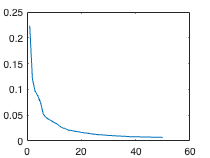

sior = n_M*n_T;
sizes = [];
for o=1:50    
    Ui = zeros(size(M));
    Ui(:,:) = phi(:, 1:o)*S(1:o, 1:o)*V(:, 1:o)';
    e = [e , norm(U-Ui)/norm(U)];
    sizes = [sizes sior-(o*(n_T+n_M+1))];
end
hold off

figure
plot(e)